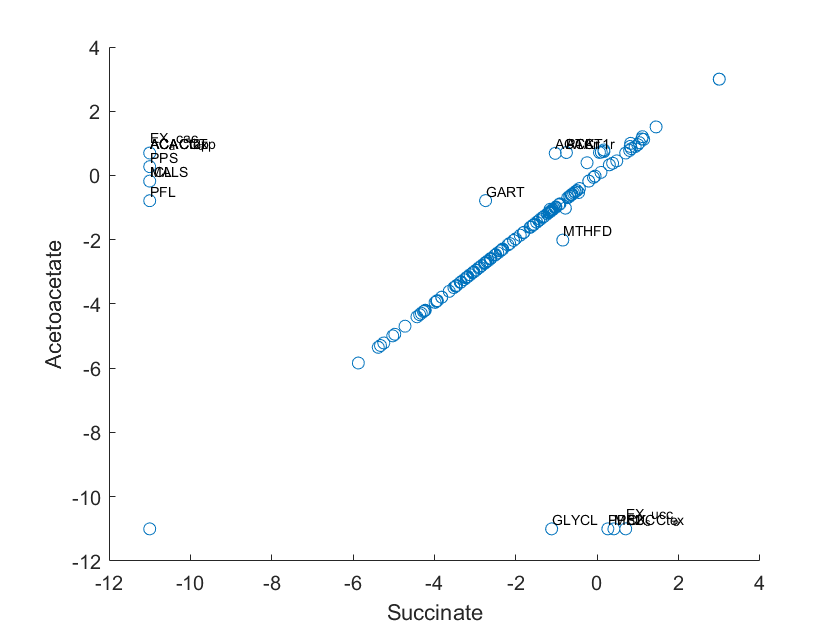

% Loading iGC1310 model
load("iGC1310");
model = iGC1310;

% Flux distribution using succinate as carbon source
model_succ = changeRxnBounds(model,'EX_nh4_e',-5,'l');
model_succ = changeRxnBounds(model_succ,'EX_succ_e',-5,'l');
new_fluxes_succ = getting_rxns_with_flux_absolute(model_succ);
log_fluxes_succinate = log10(cell2mat(new_fluxes_succ(:,2)));

% Flux distribution using Acetoacetate as carbon source
model_acac = changeRxnBounds(model,'EX_nh4_e',-5,'l');
model_acac = changeRxnBounds(model_acac,'EX_acac_e',-5,'l');
model_acac = changeRxnBounds(model_acac,'EX_succ_e',0,'l');
new_fluxes_acac = getting_rxns_with_flux_absolute(model_acac);
log_fluxes_acac = log10(cell2mat(new_fluxes_acac(:,2)));

% Reactions to label
rxns = {'ACACt2pp','ACACtex','ACACCT','EX_acac_e','PPS','ICL','MALS','PFL',...
        'GART','ACACT1r','PTAr','ACKr','MTHFD','GLYCL','ME2','PPCK',...
        'EX_succ_e','SUCCtex'}';


% Plotting scatter points
t = table(model.rxns, log_fluxes_succinate, log_fluxes_acac, ...
          'VariableNames', {'Reactions','Succinate','Acetoacetate'});

f = figure;
x = t.Succinate;
y = t.Acetoacetate;
scatter(x,y);
xlabel("Succinate")
ylabel("Acetoacetate")
hold on

idx = ismember(t.Reactions, rxns);
text(x(idx), y(idx), t.Reactions(idx), ...
     'Vert','bottom', 'Horiz','left', 'FontSize',7);